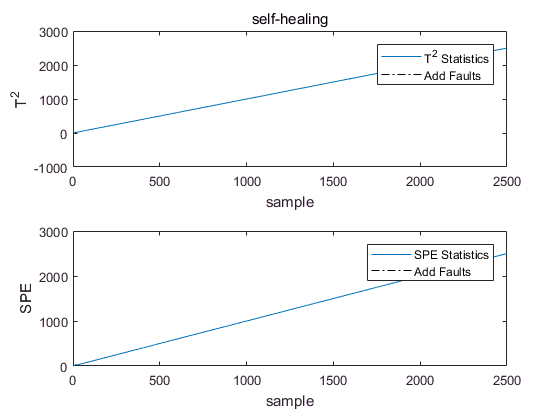

clc;
all clear;
%%%%%%%%%%%%%%%%%%%%%%%%%%CSTH数据集测试%%%%%%%%%%%%

%%%%%%   flow   temperature    level   TemperatureNoise

% x = flow;
% f = flow;
x = CWFlowDisturbance;
x = x';
f = CWFlowDisturbance;
f = f';

%%%%%%%%%%%%%%%%%%%%%绘图%%%%%%
figure
subplot(2,1,1);
length = [1:2500];    %1014 2500
% semilogy(f_T,'k')
% semilogy(z_T,'k')
plot(length,x(:,1));
line([15,15],[-20,20],'LineStyle', '-.','Color','k')
line
xlabel('sample');
ylabel('T^2');
hold on; 
legend('T^2 Statistics','Add Faults')
title('self-healing')             %%%%%PCA原来标题
subplot(2,1,2);
% semilogy(f_Q,'k')
% semilogy(z_Q,'k')

plot(length,f(:,1));
line([15,15],[0,40],'LineStyle', '-.','Color','k')
xlabel('sample');
ylabel('SPE');
hold on;
 legend('SPE Statistics','Add Faults')



%%%%%%%%%

x1 = x;
f1 = f;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%标准化%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[x_row, x_col] = size(x1);
for i = 1 : x_col
    x_mean(:, i) = ( x(:, i)-mean(x(:, i)) ) / std( x(:, i) + 1e-8);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%PCA分解%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[vector, ~, value, ~] = pca(x_mean);   %即就是生成Vector特征向量和Value特征值
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算主元数%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
k = 0;
while sum(value(1 : k)) / sum(value) < 0.85
    k = k + 1;
end 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算统计量%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1 : x_row    %T2 and Spe of training samples
     T(i) = x_mean(i, :) * vector(:, 1 : k) * inv(diag(value(1 : k, 1))) * ...
     vector(:, 1 : k)' * x_mean(i, :)';
     Q(i) = (x_mean(i, :) * vector(:, k + 1:end) * vector(:, k + 1 : end)')...
     * (x_mean(i, :) * vector(:, k + 1 : end) * vector(:, k + 1 : end)')';
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算控制限%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[Df, xx] = ksdensity(T,'function','cdf');
for i = 1 : 100   %99%控制限
    Dfmin = min(abs(Df - 0.99));
    if abs(Df(1, i) - 0.99) == Dfmin
        T2 = xx(1, i);
        break
    end
end
[Df,xx] = ksdensity(Q,'function','cdf');
for i = 1 : 100    %99%控制限
    Dfmin = min(abs(Df - 0.99));
    if abs(Df(1,i) - 0.99) == Dfmin 
        SPE = xx(1, i);
        break
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%对新样本标准化%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[f_row, f_col] = size(f1);
for i = 1 : f_col
    f_mean(:, i) = ( f(:, i)-mean(x(:, i)) ) / std( x(:, i));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
countT = 0;countSPE=0;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算统计量%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1 : f_row 
    f_T(i) = f_mean(i, :) * vector(:, 1 : k) * inv(diag(value(1 : k, 1)))...
    * vector(:, 1 : k)' * f_mean(i, :)';
    if f_T(i)>T2
        countT = countT+1;
    end
    f_Q(i) = (f_mean(i, :) * vector(:, k + 1:end) * vector(:, k + 1 : end)')...
    * (f_mean(i, :) * vector(:, k + 1 : end) * vector(:, k + 1 : end)')';
    if f_Q(i)>SPE
        countSPE = countSPE+1;
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
countT

countT = 25

countSPE

countSPE = 0

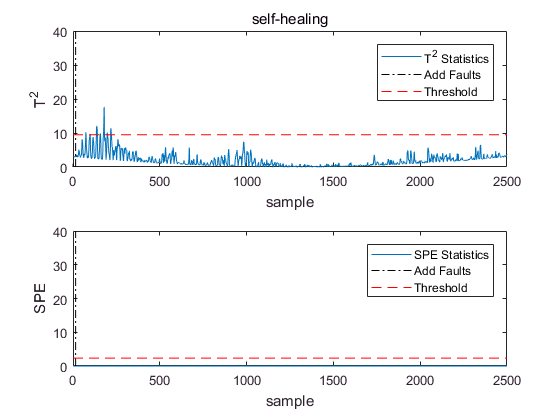

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%画图%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




figure
subplot(2,1,1);
% semilogy(f_T,'k')
% semilogy(z_T,'k')
plot(length,f_T);
line([200,200],[0,40],'LineStyle', '-.','Color','k')
% line([0,1014], [T2,T2], 'LineStyle', '--', 'Color', 'r');
line([0,2500], [T2,T2], 'LineStyle', '--', 'Color', 'r');
line
xlabel('sample');
ylabel('T^2');
hold on; 
legend('T^2 Statistics','Add Faults','Threshold')
title('self-healing')             %%%%%PCA原来标题
subplot(2,1,2);
% semilogy(f_Q,'k')
% semilogy(z_Q,'k')

plot(length,f_Q);
line([200,200],[0,40],'LineStyle', '-.','Color','k')
% line([0,1014], [SPE,SPE], 'LineStyle', '--', 'Color', 'r');
line([0,2500], [SPE,SPE], 'LineStyle', '--', 'Color', 'r');
xlabel('sample');
ylabel('SPE');
hold on;
 legend('SPE Statistics','Add Faults','Threshold')


%使用T^2、SPE统计量分别监控主元子空间与残差子空间的变化


